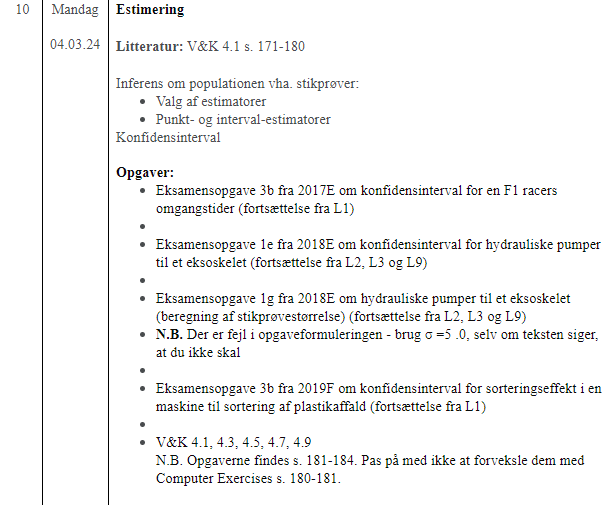

## 3b 2017E

clc; clear;

data = xlsread("Data_M4STI1_2017E.xlsx", "K:L");

deskripts(data', ["Brembo","Cl"]);



% alpha = 0.05;
% 
% finv(alpha/2,19,19)
% finv(1-alpha/2,19,19)
% 
% 
% [h,p,ci,stats]=vartest2(data(:,1), data(:,2),"Alpha",alpha,"Tail","both")


var(data(:,1))/var(data(:,2))


VarTest2pop_Test6(data(:,1), data(:,2),"right", 95, 0)


## 1E 2018E

Da populations-standardafvigelsen er ukendt, følger stikprøvenStudents-t fordeling, med n-1 frihedsgrader, hvor n er antal værdier i stikprøven
Stikprøvestandardafvigelsen beregnes


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

t-værdien findes


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\left(\frac{\alpha }{2}\,n-1\right)$$

Øvre konfidensinterval værdi


$$\bar{y}+\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

Nedre konfidensinterval værdi


$$\bar{y}-\frac{\frac{t_{\mathrm{df},\alpha }}{2}\,s}{\sqrt{n}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     97.012     "t nedre"      -3.4995      "y_bar"       103.12   
    "Øvre"      109.24     "t øvre"        3.4995      "s"           4.9407   



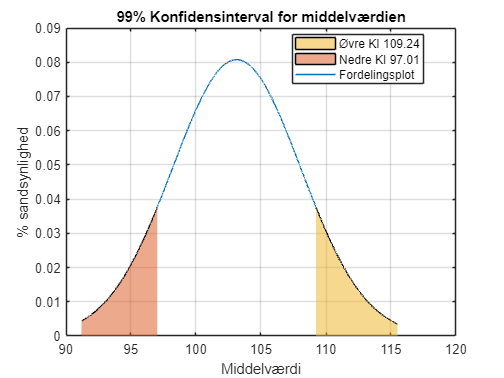

ans = struct with fields:
            KI: [2×1 double]
    test_alpha: [2×1 double]


clc; clear;
data = xlsread("Data_M4STI1_2018E (1).xlsx", 'A:A');
KonfidensIntervalNormal(data, 99, [], 103.125)

## 3b 2019

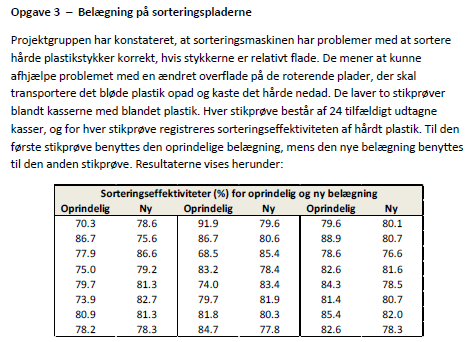

clc; clear;

data = importdata("Data_M4STI1_2019F.xlsx");
data = data.data(:,5:6)'


names = ["Oprindelig","Ny"];

deskripts(data,names)


% Oprindelig
Oprindelig = data(1,:);

KI_op = KonfidensIntervalNormal(Oprindelig, 95, [], 80.6875)
% Konfidensinterval ny
KI_ny = KonfidensIntervalNormal(data(2,:), 95, [], 80.396)

boxplot(data', 'Labels', {'Oprindelig', 'Ny'})
title('Sorteringseffektivitet for oprindelig og ny belægning')
ylabel('Sorteringseffektivitet (%)')
xlabel('Belægning')

Jamen, hypoterserne kommer til at se sådan her ud

H0: var2 = var1

Ha: var2 =/= var1

VarTest2pop_Test6(data(1,:), data(2,:),"both",95,[])

På 5% signifikansniveau er der forskel på varianserne